# Cargar información RCAT

## Declaracion de variables sobre el área de estudio

import matlab.io.hdfeos.*
clearvars -except study_area;

disp(">>> Declarando variables...ok")

>>> Declarando variables...ok


%directorio de datos
dir_data = "E:\DATA\";
%Priducto MODIS
producto = 'MOD13Q1';
% Área de estudio
archivo_kml = "Cazones";

### Obtener la lista de archivos del producto

info_hdf = f_infohdfs2table(dir_data,producto);

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1084 archivos


[num_registros_totales,~] = size(info_hdf);

#### Ventana para el mapa region hidrografica rio panuco

% % %Ventana para el mapa region hidrografica rio panuco
[lon_mapa,lat_mapa] = f_get_map_window(dir_data,archivo_kml,0.1);

[coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam,ndvi_tam]...
    = f_get_coordinates(dir_data,archivo_kml,producto,info_hdf,0.30);

>>>>> Obteniendo la zona de estudio
E:\DATA\MOD13Q1\061\*.hdf
>>>>> Analizando 1084 archivos


## Obtener latitud y longitud

if (num_registros_totales > 0)
    % Obtener matrices de latitud y longitud
    [lat,lon,ndvi] = f_get_latlon(info_hdf,coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);
end

>>>>> Obteniendo latitud y longitud


## Crear el área de estudio

% crear matriz de 0 y 1 que delimitan el área de estudio
ae = exist("study_area","var");
if ae == 0  %% no existe
    ae = exist("study_area_"+archivo_kml+"_"+producto+".mat","file");
    if ae == 2
        disp(">>> Cargando área de estudio");
        load ("study_area_"+archivo_kml+"_"+producto);

        if( numel(study_area) ~= ( ndvi_tam(1)*ndvi_tam(2)) )
            disp("La variable area_estudio sera sustituida 1");
            study_area = f_create_study_area(dir_data+'KML\'+archivo_kml+'.kml',lat,lon);
            save ("study_area_"+archivo_kml+"_"+producto+".mat",'study_area');
        else
            disp(">>> Área de estudio existente 1");
        end

    else
        study_area = f_create_study_area(dir_data+'KML\'+archivo_kml+'.kml',lat,lon);
        save ("study_area_"+archivo_kml+"_"+producto+".mat",'study_area');
    end
else
    if( numel(study_area) ~= ( ndvi_tam(1)*ndvi_tam(2)) )
        disp("La variable area_estudio sera sustituida 2");
        study_area = f_create_study_area(dir_data+'KML\'+archivo_kml+'.kml',lat,lon);
        save ("study_area_"+archivo_kml+"_"+producto+".mat",'study_area');
    else
        disp(">>> Área de estudio existente 2");
    end
end

Creando área de estudio!!!



% ndvi = double(ndvi) .* 0.0001;

## Dibujar el mapa

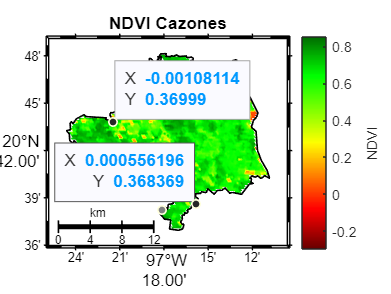

ndvi = double(ndvi) .* 0.0001;
ndvi(study_area==false)=nan;
figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi,"NDVI "+archivo_kml,[],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');

## Leer los arreglos de datos

% Realizar la consulta de los datos que se requieren
tmp = find(  info_hdf.anio >= 2000 & info_hdf.anio <= 2023 );
% tmp=find(info_hdf.anio==2022);
info_consulta = info_hdf(tmp,:);

[num_registros,~] = size(info_consulta);

% arreglo 3d de ndvi por día
arr_ndvi = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
% arreglo 3d para la calidad del pixel
arr_ndvi_qa = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
arr_ndvi_nan = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);

% arreglo 3d de ndvi por día con filtro Saviztky
arr_ndvi_sgf = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
% arreglo 3d de ndvi por día con filtro Lanczos
arr_ndvi_lf = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);

#### Leer los datos

bp=waitbar(0,'Obteniendo información de archivos MODIS'); 
for i=1:num_registros
    [ndvi,~,~,disponibilidad] = f_get_ndvi(info_consulta(i,:),coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

    % recortar el area de estudio
    ndvi(study_area==false)=NaN;
    disponibilidad(study_area==false)=NaN;

    %almacenar en el arreglo en 3d
    arr_ndvi(:,:,i) = ndvi;
    arr_ndvi_qa(:,:,i) = disponibilidad;
 
    arr_ndvi_lf(:,:,i) = ndvi;
    arr_ndvi_sgf(:,:,i) = ndvi;

    %barra de progreso
    waitbar(i/num_registros,bp,sprintf('Obteniendo información de archivos MODIS (%3.0f%%) ',(i/num_registros*100)));
end
close(bp); 


% bp=waitbar(0,'Generando series de tiempo con interpolación'); 
% for i=1:ndvi_tam(1)
%      for j=1:ndvi_tam(2)
%          if study_area(i,j) == true
%             arr_ndvi_nan(i,j,:) = f_rm_pixel_baja_calidad(arr_ndvi(i,j,:),arr_ndvi_qa(i,j,:));
%             arr_ndvi_com(i,j,:) =  f_fillmissing_linear(arr_ndvi_nan(i,j,:),0);
%          end
% 
%      end
%      waitbar(i/ndvi_tam(1),bp,sprintf('Generando series de tiempo con interpolación (%3.0f%%) ',(i/ndvi_tam(1)*100)));
% end
% close (bp);

#### Mostrar el promedio de NDVI

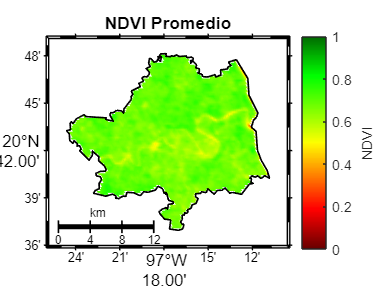

ndvi_prom = f_mean_3dpp(arr_ndvi);
ndvi_prom(study_area==false)=nan;

f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"NDVI Promedio",[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');

## Filtrar con Lanczos y Savitzky-Golay 

%Mejores parametros para el filtro Lanczos
dT = 23;
cf= 1/46;

% Mejores parametros para Savitzky-Golay
order = 3;
framelen = 7;

bp=waitbar(0,'Generando series de tiempo con filtros'); 
for i=1:ndvi_tam(1)
     for j=1:ndvi_tam(2)
         if study_area(i,j) == true

             S  = reshape( arr_ndvi(i,j,:),[],1);
             SNan =  reshape( arr_ndvi_nan(i,j,:),[],1);

             arr_ndvi_nan(i,j,:) = f_rm_pixel_baja_calidad(arr_ndvi(i,j,:),arr_ndvi_qa(i,j,:));

             [arr_ndvi_nan(i,j,:),~] = f_fillmissing_linear(arr_ndvi_nan(i,j,:),2);

             [xs,~,~,~,~] = lanczosfilter(S,dT,cf,[],'low');  
             arr_ndvi_lf(i,j,:) = xs;

             arr_ndvi_sgf(i,j,:) = sgolayfilt(S,order,framelen);

         end

     end
     waitbar(i/ndvi_tam(1),bp,sprintf('Generando series de tiempo con filtros (%3.0f%%) ',(i/ndvi_tam(1)*100)));
end
close (bp);

#### Mostrar el promedio de NDVI FILTRO SAVITZKY de toda la serie

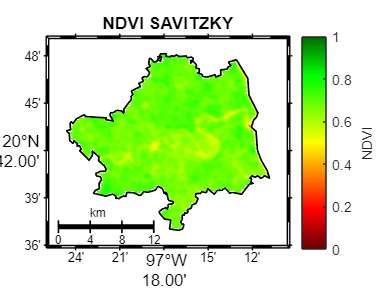

ndvi_prom = f_mean_3dpp(arr_ndvi_sgf);
ndvi_prom(study_area==false)=nan;

figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"NDVI SAVITZKY",[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');


% exportgraphics(gca,"img/RCAT01_promedio.png",'Resolution',300) 


## Serie de tiempo

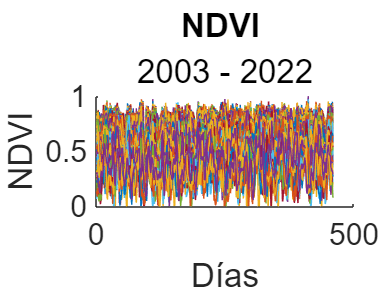

indxs=find(info_hdf.anio>=2003 & info_hdf.anio<=2022);
% indxs=find(info_hdf.anio==2022);
mean_temp=arr_ndvi_sgf(:,:,indxs);
[alto,ancho,~]=size(mean_temp);
figure; 
hold on
for i=1:alto
     for j=1:ancho
        if(study_area(i,j)==1)
            serie = reshape(mean_temp(i,j,:),[],1);
            plot(serie)
        end
    end
end
hold off

%title('NDVI promedio x estación');
xlabel('Días','FontSize',18);
% xticks(1:length(linea_tiempo_promedio));
% xticklabels(lbl_ejex);
ylabel('NDVI','FontSize',18);
% xlim([0 (length(linea_tiempo_promedio)+1)]);
ylim([0 1]);

% xtickangle(45);
ax = gca;
ax.FontSize=18; 
title("NDVI "," 2003 - 2022 ")

% title("NDVI"," Cultivo 3 ("+2022+")")
% exportgraphics(gca,"img/RCAT01_grafica.png",'Resolution',300);


## Promedio diario en un año/2003-2022

% indx=find(info_hdf.anio==2022);
indx=find(info_hdf.anio>=2003 & info_hdf.anio<=2022);
arr_ndvi_temp=arr_ndvi_sgf(:,:,indx);
[~,~,sr]=size(arr_ndvi_temp);
p_mes_ndvi_sv_d=[];
for i=1:sr
    p_mes_ndvi_m1(i)=mean(arr_ndvi_temp(:,:,i),"all","omitnan");
    p_mes_ndvi_sv_d(i)=mean(arr_ndvi_temp(:,:,i),"all","omitnan");
end


figure
hold on
% plot(p_mes_ndvi_m1);
[a0,a1,ajuste]=f_reglin(1:length(p_mes_ndvi_sv_d),p_mes_ndvi_sv_d)

a0 = 0.6697

a1 = 7.9862e-06

ajuste =     0.6697    0.6697    0.6697    0.6697    0.6697    0.6697    0.6698    0.6698    0.6698    0.6698    0.6698    0.6698    0.6698    0.6698    0.6698    0.6698    0.6698    0.6698    0.6699    0.6699    0.6699    0.6699    0.6699    0.6699    0.6699    0.6699    0.6699    0.6699    0.6699    0.6699    0.6699    0.6700    0.6700    0.6700    0.6700    0.6700    0.6700    0.6700    0.6700    0.6700    0.6700    0.6700    0.6700    0.6701    0.6701    0.6701    0.6701    0.6701    0.6701    0.6701


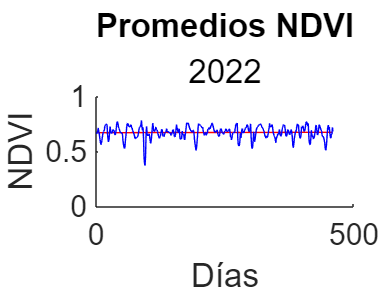


plot(ajuste,"r")

plot( p_mes_ndvi_sv_d,"b");
ylim([0 1]);
ax = gca;
ax.FontSize=18; 
xlabel("Días")
ylabel("NDVI")
% xlim([1 23])
hold off
title("Promedios NDVI","2022")

% title("Promedio NDVI","2003 - 2022")
% legend("NDVI","Location","southeast")
[a,b]=max(p_mes_ndvi_sv_d)

a = 0.7816

b = 88


[a,b]=min(p_mes_ndvi_sv_d)

a = 0.3705

b = 95

Regresion liean ajuste primero los parametros anteriores

## **Promedio Mensual de NDVI (2003-2022 )**

init=2003;
finish=2022;
tmp = find(  info_hdf.anio >= init & info_hdf.anio <= finish );
arr_ndvi_sgf (study_area==false)=nan;
promedio_mes_ndvi=[];
idx_ea=2;
for mes=1:12
    promedio_mes_ndvi(mes,1)=mes;
    for eag=init:finish
        indx_month=find(info_hdf.anio==eag & info_hdf.mes==mes);
        promedio_mes_ndvi(mes,idx_ea)=mean(arr_ndvi_sgf(:,:,indx_month),"all","omitnan");
        idx_ea=idx_ea+1;
    end
    idx_ea=2;
end

Graficar Promedios Mensuales

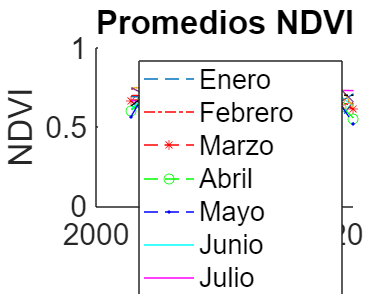

figure 
hold on
meses=["Enero","Febrero","Marzo","Abril","Mayo","Junio","Julio","Agosto","Septiembre","Octubre","Noviembre","Diciembre"];
% plot(init:finish ,promedio_mes_ndvi(10:12,2:21));
plot(init:finish ,promedio_mes_ndvi(1,2:21),'--');
plot(init:finish ,promedio_mes_ndvi(2,2:21),'r-.');
plot(init:finish ,promedio_mes_ndvi(3,2:21),'r--*');
plot(init:finish ,promedio_mes_ndvi(4,2:21),'g--o');
plot(init:finish ,promedio_mes_ndvi(5,2:21),'b--.');
plot(init:finish ,promedio_mes_ndvi(6,2:21),'c');
plot(init:finish ,promedio_mes_ndvi(7,2:21),'m');
plot(init:finish ,promedio_mes_ndvi(8,2:21));
plot(init:finish ,promedio_mes_ndvi(9,2:21),':');
plot(init:finish ,promedio_mes_ndvi(10,2:21));
plot(init:finish ,promedio_mes_ndvi(11,2:21));
plot(init:finish ,promedio_mes_ndvi(12,2:21),'k-.');

ylim([0 1]);
ax = gca;
ax.FontSize=18; 
xlabel("Años")
ylabel("NDVI")

hold off
title("Promedios NDVI")
legend( meses,"Location","southeast")

% legend("NDVI","NDVI Savitzky","Location","southeast")


## **Promedio Mensual de NDVI (2022)**

init=2022;
finish=2022;
tmp = find(  info_hdf.anio >= init & info_hdf.anio <= finish );
% arr_ndvi_sgf (study_area==false)=nan;
promedio_mes_ndvi_ea=[];
idx_ea=2;
for mes=1:12
    for eag=init:finish
        indx_month=find(info_hdf.anio==eag & info_hdf.mes==mes);
        promedio_mes_ndvi_ea(mes,1)=mes;
        promedio_mes_ndvi_ea(mes,idx_ea)=mean(arr_ndvi_sgf(:,:,indx_month),"all","omitnan");
        idx_ea=idx_ea+1;
    end
    idx_ea=2;
end

## **Graficar Promedios Mensuales**

figure 
hold on
serie_p=promedio_mes_ndvi_ea(:,2);
[a02,a12,ajuste_2]=f_reglin(1:length(serie_p'),serie_p')

a02 = 0.6008

a12 = 0.0061

ajuste_2 =     0.6069    0.6130    0.6191    0.6252    0.6313    0.6374    0.6435    0.6495    0.6556    0.6617    0.6678    0.6739


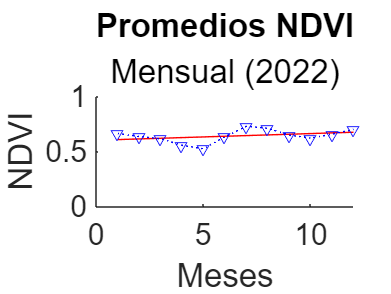


plot(ajuste_2,"r")
plot(1:12,promedio_mes_ndvi_ea(:,2),'b:v');


ylim([0 1]);
ax = gca;
ax.FontSize=18; 
xlabel("Meses")
ylabel("NDVI")

hold off
title("Promedios NDVI","Mensual (2022)")

% legend(,"Location","southeast")
% legend("NDVI","NDVI Savitzky","Location","southeast")

Promedio Por año NDVI (2003-2022)

figure
init= 2003 %info_hdf.anio(1)

init = 2003

finish= 2022 %info_hdf.anio(size(info_hdf,1))

finish = 2022

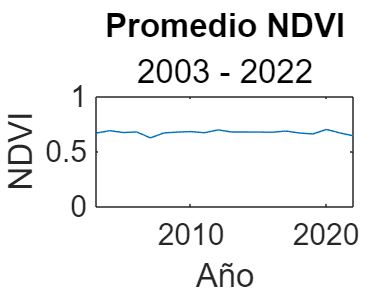

% mes=[];
% ps_1=[];
eage_temp_sv=[];
mean_eage_sv=[];
pivot=1;
for i=init:finish
    eage_temp_sv{pivot}=find(info_hdf.anio==i);
%     mx_temp=mean(arr_ndvi_sgf(:,:,eage_temp_sv{pivot}),"all","omitnan");
    mx_temp=f_mean_3dpp(arr_ndvi_sgf(:,:,eage_temp_sv{pivot}));
    mx_temp(study_area==false)=nan;
    mean_eage_sv(pivot)=mean(mx_temp,"all","omitnan");
    pivot=pivot+1;
end

% Graficando promerio por año 
plot(2003:2022,mean_eage_sv);
title('Promedio NDVI','2003 - 2022')
ylim([0 1]);
xlim([2003 2022])
ax = gca;
ax.FontSize=18; 

xlabel("Año")
ylabel("NDVI")
hold off

max(mean_eage_sv)

ans = 0.6997

min(mean_eage_sv)

ans = 0.6224

Promedio Por Estacion anual

figure
init=2003;
finish=2022;
tmp = find(  info_hdf.anio >= init & info_hdf.anio <= finish );
arr_ndvi_sgf (study_area==false)=nan;
mean_estacion_sv=[];
idx_ea=2;
for est=1:4
    for eag=init:finish
        indx_month=find(info_hdf.anio==eag & info_hdf.estacion==est);
        mean_estacion_sv(est,1)=est;
        mean_estacion_sv(est,idx_ea)=mean(arr_ndvi_sgf(:,:,indx_month),"all","omitnan");
        idx_ea=idx_ea+1;
    end
    idx_ea=2;
end



Graficar Estaciones anuales

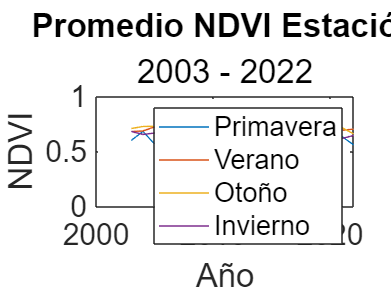

figure
plot(init:finish, mean_estacion_sv(:,2:21));
xlabel("Año")
ylabel("NDVI")
title('Promedio NDVI Estación','2003 - 2022')
ylim([0 1]);
legend("Primavera","Verano","Otoño","Invierno")
ax = gca;
ax.FontSize=18; 

Estaciones Promedio

[ancho,alto,~]= size(arr_ndvi_sgf)

ancho = 141

alto = 97

 mean_only_estacion= zeros(ancho,alto,4);
for est=1:4
    indxs=find(info_hdf.estacion==est &  info_hdf.anio>=2003 &  info_hdf.anio<=2022);
%     mean_only_estacion(est,1)=est;
    mean_only_estacion(:,:,est) =f_mean_3dpp(arr_ndvi_sgf(:,:,indxs));
end

Pintando mapas por estacion

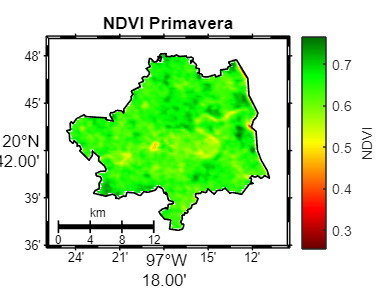


indxs=find(info_hdf.estacion==1 &  info_hdf.anio>=2003 &  info_hdf.anio<=2022);
mean_temp=f_mean_3dpp(arr_ndvi_sgf(:,:,indxs));
mean_temp(study_area==false)=nan;
figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,mean_temp,"NDVI Primavera",[],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');

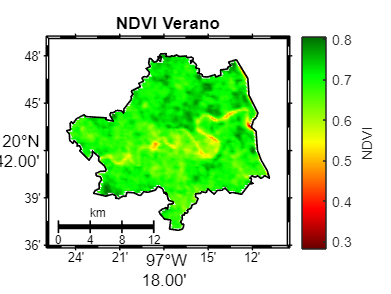


indxs=find(info_hdf.estacion==2 &  info_hdf.anio>=2003 & info_hdf.anio<=2022);
mean_temp=f_mean_3dpp(arr_ndvi_sgf(:,:,indxs));
mean_temp(study_area==false)=nan;
figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,mean_temp,"NDVI Verano",[],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');

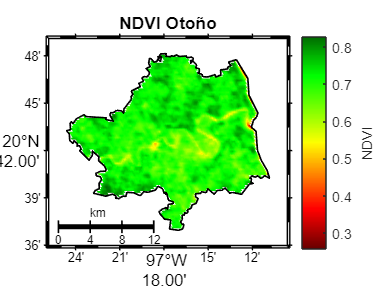


indxs=find(info_hdf.estacion==3 &  info_hdf.anio>=2003 & info_hdf.anio<=2022);
mean_temp=f_mean_3dpp(arr_ndvi_sgf(:,:,indxs));
mean_temp(study_area==false)=nan;
figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,mean_temp,"NDVI Otoño",[],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');

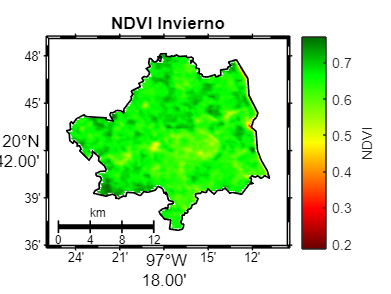


indxs=find(info_hdf.estacion==4  &  info_hdf.anio>=2003 & info_hdf.anio<=2022);
mean_temp=f_mean_3dpp(arr_ndvi_sgf(:,:,indxs));
mean_temp(study_area==false)=nan;
figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,mean_temp,"NDVI Invierno",[],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');

Promedios

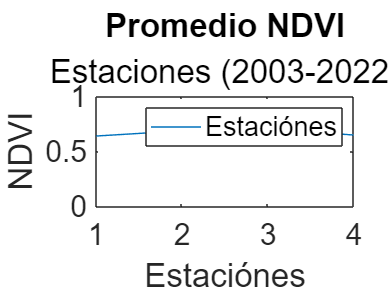

mean_estaciones=[];
for i=1:4
    mean_estaciones(1,i)=mean(mean_only_estacion(:,:,i),"all","omitnan");
end

figure

plot(1:4,mean_estaciones);
xlabel("Estaciónes")
ylabel("NDVI")
title("Promedio NDVI","Estaciones (2003-2022)")
ylim([0 1]);
legend("Estaciónes")
ax = gca;
ax.FontSize=18; 
hold off;

## Promedio de años respecto a los dias 

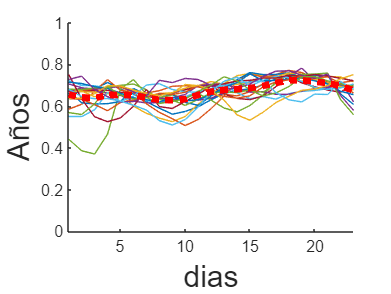


[ancho,alto,~]=size(arr_ndvi_sgf);

% temp_ndvi=zeros(ancho,alto,23);
mean_ea_dia_s=[];
apoyo=1;

for i=2003:2022
    for a=1:23
        indexes=find(info_hdf.anio==i);
        temp_arr=arr_ndvi_sgf(:,:,indexes);
        mean_ea_dia_s(apoyo,a)=mean(temp_arr(:,:,a),"all","omitnan");
    end
    apoyo=apoyo+1;
end

mean_dias=mean(mean_ea_dia_s);

figure
hold on


[a,b]=size(mean_ea_dia_s);

for i=1:a
    plot(mean_ea_dia_s(i,:));
end


% plot(mean_ea_dia_s');
plot(mean_dias ,":r","LineWidth",4)
ylim([0 1]);
xlim([1 23])
ylabel("Años","FontSize",18)
xlabel("dias","FontSize",18)

hold off

max(mean_dias)

ans = 0.7239

min(mean_dias)

ans = 0.6284

## Producción